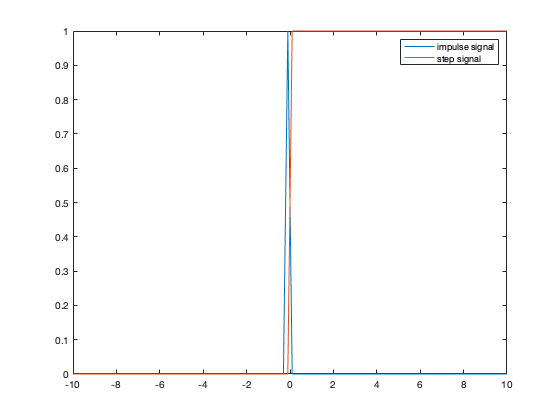

x = linspace(-10,10,100);

%unit impulse signal
imp = zeros([1 100]);
imp(50) = 1;
plot(x,imp)
hold on

%unit step signal
stp = [zeros([1,50]), ones([1,50])];
plot(x,stp)
legend(["impulse signal","step signal"]);
hold off

%square wave
T=2*pi

T = 6.2832

sampling_freq=100

sampling_freq = 100

x = 0:T/sampling_freq:(T+(T/sampling_freq))

x =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221    1.8850    1.9478    2.0106    2.0735    2.1363    2.1991    2.2619    2.3248    2.3876    2.4504    2.5133    2.5761    2.6389    2.7018    2.7646    2.8274    2.8903    2.9531    3.0159    3.0788


x=[x,x+T]

x =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221    1.8850    1.9478    2.0106    2.0735    2.1363    2.1991    2.2619    2.3248    2.3876    2.4504    2.5133    2.5761    2.6389    2.7018    2.7646    2.8274    2.8903    2.9531    3.0159    3.0788



sq = square(x)

sq =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


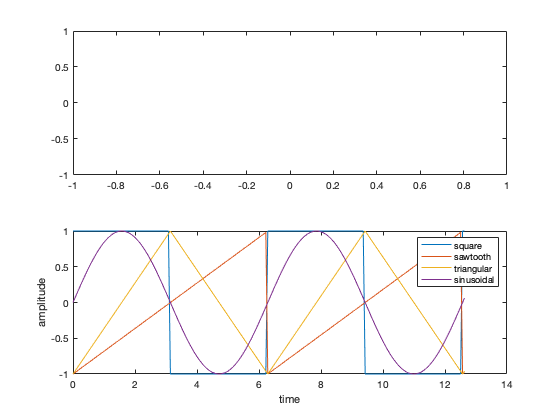

plot(x,sq)
hold on

%sawtooth wave
saw=sawtooth(x);
plot(x,saw)

%triangular wave
tri = sawtooth(x,1/2);
plot(x,tri)

%sinusoidal wave
sinu = sin(x);
plot(x,sinu)
legend('square','sawtooth','triangular','sinusoidal')
xlabel('time')
ylabel('amplitude')
hold off

%scaling
scal = sinu+1

scal =     1.0000    1.0628    1.1253    1.1874    1.2487    1.3090    1.3681    1.4258    1.4818    1.5358    1.5878    1.6374    1.6845    1.7290    1.7705    1.8090    1.8443    1.8763    1.9048    1.9298    1.9511    1.9686    1.9823    1.9921    1.9980    2.0000    1.9980    1.9921    1.9823    1.9686    1.9511    1.9298    1.9048    1.8763    1.8443    1.8090    1.7705    1.7290    1.6845    1.6374    1.5878    1.5358    1.4818    1.4258    1.3681    1.3090    1.2487    1.1874    1.1253    1.0628


plot(x,scal)
hold on
plot(x,sinu)
hold off

%folding
foldi = sin(-x)

foldi =          0   -0.0628   -0.1253   -0.1874   -0.2487   -0.3090   -0.3681   -0.4258   -0.4818   -0.5358   -0.5878   -0.6374   -0.6845   -0.7290   -0.7705   -0.8090   -0.8443   -0.8763   -0.9048   -0.9298   -0.9511   -0.9686   -0.9823   -0.9921   -0.9980   -1.0000   -0.9980   -0.9921   -0.9823   -0.9686   -0.9511   -0.9298   -0.9048   -0.8763   -0.8443   -0.8090   -0.7705   -0.7290   -0.6845   -0.6374   -0.5878   -0.5358   -0.4818   -0.4258   -0.3681   -0.3090   -0.2487   -0.1874   -0.1253   -0.0628


plot(x,sinu)
hold on
plot(-x,foldi)
hold off

%shifting
x2 = x+0.4

x2 =     0.4000    0.4628    0.5257    0.5885    0.6513    0.7142    0.7770    0.8398    0.9027    0.9655    1.0283    1.0912    1.1540    1.2168    1.2796    1.3425    1.4053    1.4681    1.5310    1.5938    1.6566    1.7195    1.7823    1.8451    1.9080    1.9708    2.0336    2.0965    2.1593    2.2221    2.2850    2.3478    2.4106    2.4735    2.5363    2.5991    2.6619    2.7248    2.7876    2.8504    2.9133    2.9761    3.0389    3.1018    3.1646    3.2274    3.2903    3.3531    3.4159    3.4788


x3 = x-1

x3 =    -1.0000   -0.9372   -0.8743   -0.8115   -0.7487   -0.6858   -0.6230   -0.5602   -0.4973   -0.4345   -0.3717   -0.3088   -0.2460   -0.1832   -0.1204   -0.0575    0.0053    0.0681    0.1310    0.1938    0.2566    0.3195    0.3823    0.4451    0.5080    0.5708    0.6336    0.6965    0.7593    0.8221    0.8850    0.9478    1.0106    1.0735    1.1363    1.1991    1.2619    1.3248    1.3876    1.4504    1.5133    1.5761    1.6389    1.7018    1.7646    1.8274    1.8903    1.9531    2.0159    2.0788


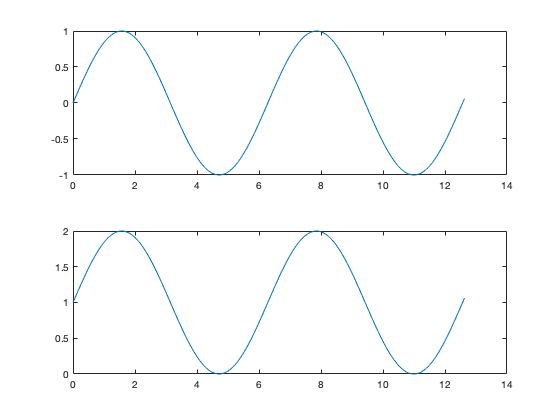

plot(x,sinu)
hold on
plot(x3,sinu)
plot(x2,sinu)
hold off

subplot(2,1,1)
plot(x,sinu)
subplot(2,1,2)
plot(x,scal)

T = 1/5;
T_samp = 0.01;
T_total = 2;
t_start = -1;
t = t_start:T_samp:t_start+T_total;
sinu = sin((2*pi*t)/T);
plot(t,sinu)
hold on

cosi = cos((2*pi*t)/T);

cosi =     1.0000    0.9511    0.8090    0.5878    0.3090   -0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090    0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090   -0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090    0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511


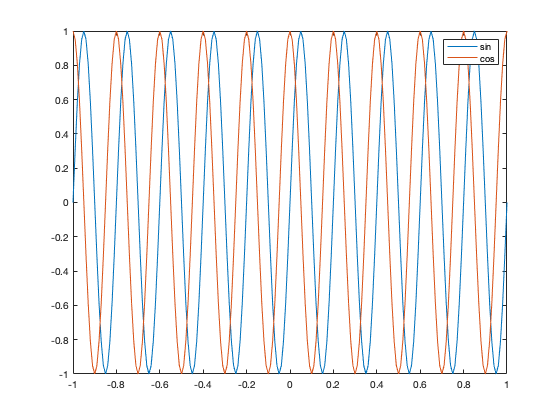

plot(t,cosi)
hold off
legend('sin','cos');


%observations
%both signals are 90 degree out of phase.

f1 = 4;
f2 = 8;
T_samp = 0.01;
T_total = 1;
t_start = -1;
t = t_start:T_samp:t_start+T_total;

sinu1 = sin(2*pi*f1*t);
sinu2 = sin(2*pi*f2*t);
plot(t,sinu1)
hold on
plot(t,sinu2)

%addition of signals
sinu_add = sinu1+sinu2

sinu_add =     0.0000    0.7304    1.3261    1.6826    1.7492    1.5388    1.1234    0.6142    0.1343   -0.2118   -0.3633   -0.3164   -0.1234    0.1234    0.3164    0.3633    0.2118   -0.1343   -0.6142   -1.1234   -1.5388   -1.7492   -1.6826   -1.3261   -0.7304    0.0000    0.7304    1.3261    1.6826    1.7492    1.5388    1.1234    0.6142    0.1343   -0.2118   -0.3633   -0.3164   -0.1234    0.1234    0.3164    0.3633    0.2118   -0.1343   -0.6142   -1.1234   -1.5388   -1.7492   -1.6826   -1.3261   -0.7304


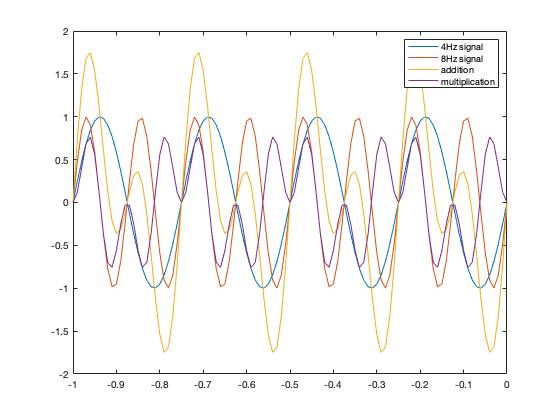

plot(t,sinu_add)

%multiplication of signals
sinu_mult = sinu1.*sinu2;
plot(t,sinu_mult)
hold off
legend(string(f1)+'Hz signal',string(f2)+'Hz signal','addition','multiplication');


%mean
disp('mean : '+string(mean(sinu_add)))

mean : -5.4962e-17


disp('mean : '+string(mean(sinu_mult)))

mean : -3.0559e-16



%variance
disp('variance : '+string(var(sinu_add)))

variance : 1


disp('variance : '+string(var(sinu_mult)))

variance : 0.25



%rms
disp('rms : '+string(rms(sinu_add)))

rms : 0.99504


disp('rms : '+string(rms(sinu_mult)))

rms : 0.49752


T_total = 1;
t_start = 0;
t = linspace(t_start,t_start+T_total,500)

t =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0261    0.0281    0.0301    0.0321    0.0341    0.0361    0.0381    0.0401    0.0421    0.0441    0.0461    0.0481    0.0501    0.0521    0.0541    0.0561    0.0581    0.0601    0.0621    0.0641    0.0661    0.0681    0.0701    0.0721    0.0741    0.0762    0.0782    0.0802    0.0822    0.0842    0.0862    0.0882    0.0902    0.0922    0.0942    0.0962    0.0982


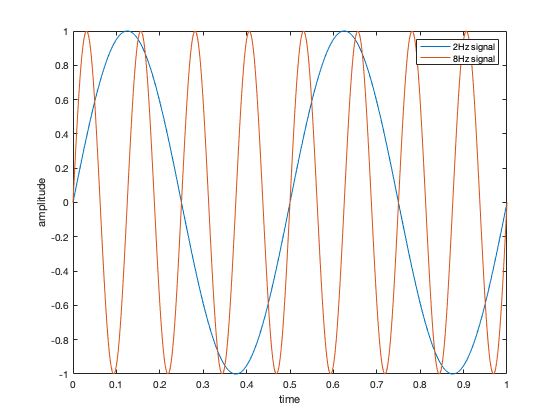


f1 = 2;
sinu1 = sin(2*pi*f1*t);
plot(t,sinu1)
hold on

f2 = 8;
sinu2 = sin(2*pi*f2*t);
plot(t,sinu2)
hold off
legend(string(f1)+'Hz signal',string(f2)+"Hz signal")
xlabel('time')
ylabel('amplitude')


x = dot(sinu1,sinu2)

x = -8.7014e-15

% Since x is almost zero 
% ==>> waves are orthogonal.

gauss_rand_nums = randn([1 2000])

gauss_rand_nums =     1.3056    0.9840   -1.2514   -0.1798   -0.7434    0.2332    2.1013   -0.8767    1.9488   -0.4653   -0.6519    0.6096    0.7091    0.2798   -1.4675   -0.6913   -0.8680   -0.5125   -0.7821    0.4258    1.0115   -0.2507    0.5542    0.7589    0.1338   -0.2726   -0.5426   -1.1631   -0.2735    0.1595   -0.1867    0.2179    0.0462    0.6703   -0.6305   -0.1184    0.2421   -0.3761    0.2804   -1.7745    0.4586    0.4618   -0.0012   -0.3529   -0.4330   -1.7048    1.0957    0.6358   -1.0872   -1.4773


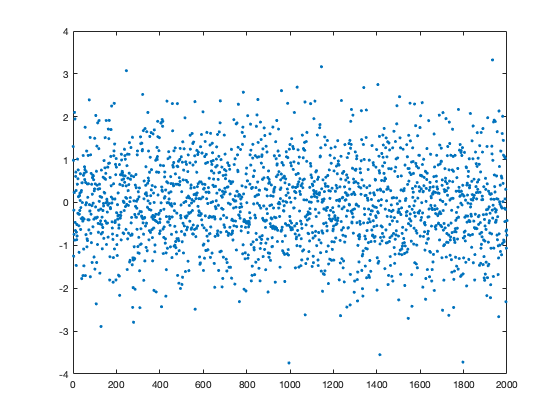

plot(gauss_rand_nums,'.')

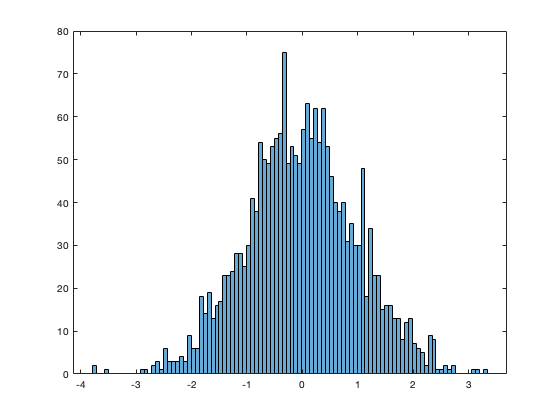

histogram(gauss_rand_nums,100)

disp('mean : '+string(mean(gauss_rand_nums)))

mean : -0.01424


disp('standard deviation : '+string(std(gauss_rand_nums)))

standard deviation : 0.99347


disp('variance : '+ string(var(gauss_rand_nums)))

variance : 0.98699


disp('skewness : '+ string(skewness(gauss_rand_nums)))

skewness : 0.014468


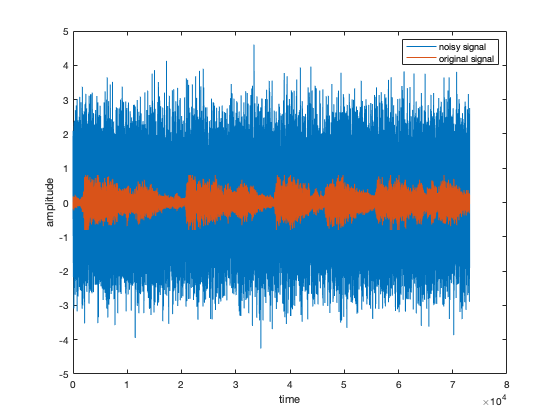

a = load('handel.mat');
audiowrite('abc.wav',a.y,a.Fs);
[y, fs] = audioread("abc.wav");
%soundsc(y,fs);

%random noise
noise = randn(size(y));
%soundsc(y+noise,fs);

plot(y+noise)
hold on
plot(y)
hold off
legend('noisy signal','original signal')
xlabel('time');
ylabel('amplitude');

%convolution
disp(conv(sinu1,sinu2))

  Columns 1 through 5

         0         0    0.0025    0.0101    0.0252

  Columns 6 through 10

    0.0501    0.0871    0.1384    0.2059    0.2915

  Columns 11 through 15

    0.3967    0.5229    0.6714    0.8429    1.0383

  Columns 16 through 20

    1.2578    1.5017    1.7698    2.0617    2.3767

  Columns 21 through 25

    2.7140    3.0722    3.4501    3.8459    4.2577

  Columns 26 through 30

    4.6835    5.1211    5.5679    6.0216    6.4793

  Columns 31 through 35

    6.9385    7.3962    7.8498    8.2963    8.7330

  Columns 36 through 40

    9.1571    9.5660    9.9570   10.3279   10.6762

  Columns 41 through 45

   10.9999   11.2971   11.5662   11.8055   12.0140

  Columns 46 through 50

   12.1907   12.3349   12.4462   12.5244   12.5697

  Columns 51 through 55

   12.5824   12.5633   12.5133   12.4335   12.3255

  Columns 56 through 60

   12.1909   12.0315   11.8493   11.6467   11.4260

  Columns 61 through 65

   11.1896   10.9402   10.6803   10.4127   10.1401

  

%signal
f_samp = 1000;
t_start = 0;
Total_points = 1024;
t_2 = zeros([1 Total_points])

t_2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y = zeros([1 Total_points])

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


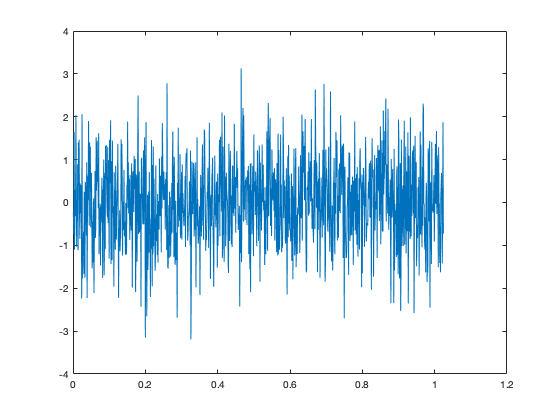

for i=1:Total_points
    t_2(i) = t_start+i*(1/f_samp);
    y(i) = randn(1);
end
plot(t_2,y)

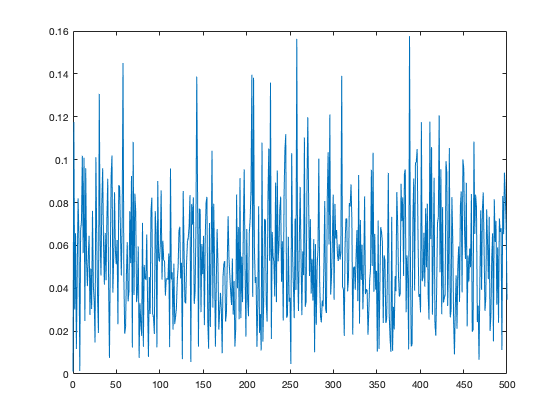


%Fourier Transform
Fourier_trans = fft(y);

P2 = abs(Fourier_trans/Total_points);
P1 = P2(1:Total_points/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = f_samp*(0:(Total_points/2))/Total_points;
plot(f,P1)